% Dimensiones del robot
L1 = 486.5/100; L2 = 150/100; L3 = 700/100; L4=600/100; L5 = 65/100; 

% Robot 6R
ws =  1.5* [-10 10 -10 10 -10 10];ws =  1.5* [-10 10 -10 10 -10 10];      % Espacio de trabajo
plot_options = {'workspace',ws,'scale',.5,'view',[125 25], 'tilesize',2,  'ortho',...
                'lightpos',[2 2 10] };

% Eslabones y articulaciones
%            Theta  d   a   alpha  type mdh offset  qlim
L(1) = Link('revolute', 'alpha', 0, 'a', 0, 'd', L1, 'offset', 0, 'qlim', [-pi pi], 'modified');
L(2) = Link('revolute', 'alpha', pi/2, 'a', L2, 'd', 0, 'offset', pi/2, 'qlim', [-pi/2 deg2rad(150)], 'modified');
L(3) = Link('revolute', 'alpha', 0, 'a', L3, 'd', 0, 'offset', 0, 'qlim', [deg2rad(-238) deg2rad(79)], 'modified');
L(4) = Link('revolute', 'alpha', pi/2, 'a', 0, 'd', L4, 'offset', 0, 'qlim', [deg2rad(-155) deg2rad(155)], 'modified');
L(5) = Link('revolute', 'alpha', -pi/2, 'a', 0, 'd', 0, 'offset', 0, 'qlim', [-pi/2 3*pi/4], 'modified');
L(6) = Link('revolute', 'alpha', pi/2, 'a', 0, 'd', 0, 'offset', 0, 'qlim', [deg2rad(-200) deg2rad(200)], 'modified');

% Representación del robot     
Robot = SerialLink(L,'name', 'Robot_{6R}', 'plotopt', plot_options);
Robot.tool = [  -1  0   0  0;...     % Nuevo valor TCP
                 0  -1   0  0 ;...
                 0  0   1  L5 ;...
                 0  0   0  1  ];

% Representación del robot
q = [0 0 0 0 0 0];
Robot.plot(q)  % Dibujar el robot

### Modelo geométrico inverso:

1. Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase.

Para halla el modelo geométrico del robot ABB IRB 1600 se toma una configuración codo arriba como se muestra en la figura a continuación:

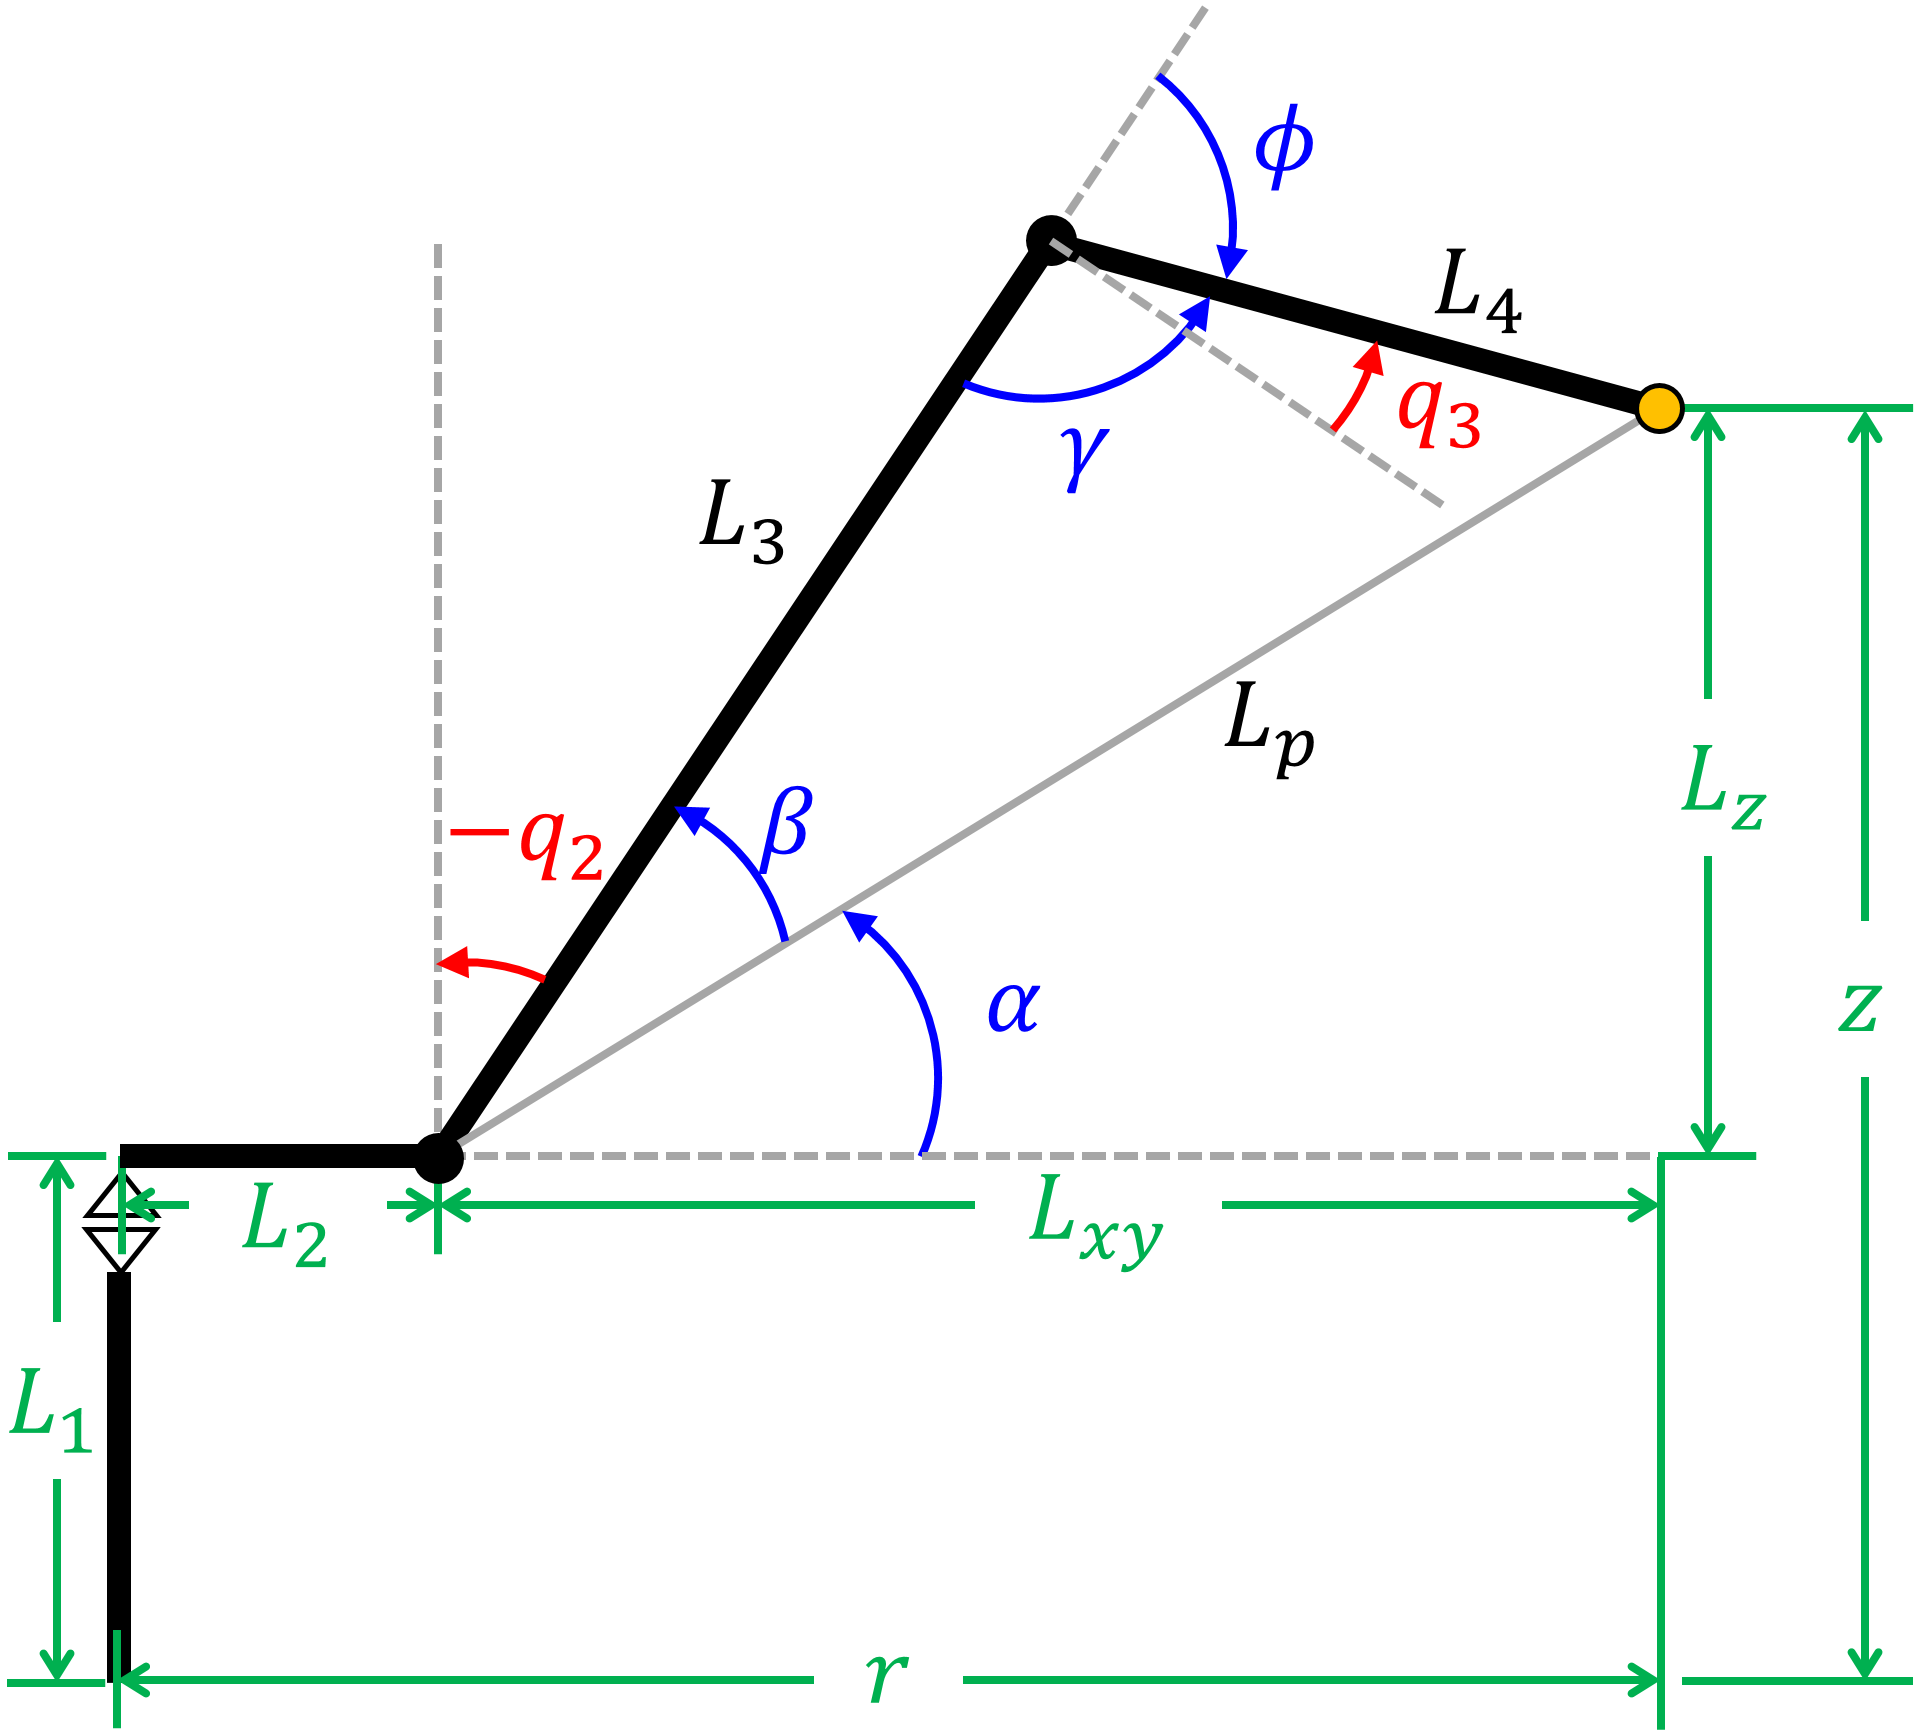

Primero se halla la posición de la muñeca, para esto, se le resta al vector de posición del efector final el vector desde el TCP hasta la muñeca, así:


$$\vec{p_e} = x_e \hat{\imath} + y_e \hat{\jmath} + z_e \hat{k}$$



$$\vec{p_w} = \vec{p_e} - L_5 \vec{a_6} = x_w \hat{\imath} + y_w \hat{\jmath} + z_w \hat{k}$$



$$q_1 = atan2(y_w,x_w)$$


% Valores de prueba
xe = 750/100;
ye = 100/100;
ze = 593/100;
roll = -45;
pitch = 0;
yaw = -90;

R0T = rpy2r(roll, pitch, yaw, 'deg');   % Matriz rotación efector final

pe = [xe; ye; ze];      % Coordenadas efector final
pw = pe - L5*R0T(:,3);  % Coordenadas muñeca
xw = pw(1);             % Coordenada x muñeca
yw = pw(2);             % Coordenada y muñeca
zw = pw(3);             % Coordenada z muñeca

q1 = atan2(yw,xw)       % Valor q1 

q1 = 0.0719

Se calculan los valores de $r$, $L_{xy}$, $L_z$ y $L_p$ que se muestran en la figura:


$$r = \sqrt{x_w^2 + y_w^2}$$



$$L_{xy} = r - L_2$$



$$L_z = z_w - L_1$$



$$L_p = \sqrt{L_{xy}^2 + L_z^2}$$


r = sqrt(xw^2 + yw^2);
Lxy = r - L2;
Lz = zw - L1;
Lp = sqrt(Lxy^2 + Lz^2);

Luego se calcula el valor $q_2$ teniendo en cuenta los ángulos $\alpha$, $\beta$ y las identidades trigonométricas.


$$\alpha = atan2(L_z, L_{xy})$$


Usando la ley del coseno y despejando:


$$L_4^2 = L_3^2 + L_p^2 - 2 L_3 L_p cos \beta$$



$$cos \beta = \frac{L_3^2 + L_p^2 - L_4^2}{2 L_3 L_p}$$



$$sen \beta  = \sqrt{1 - cos \beta^2}$$



$$\beta = atan2(sen \beta, cos \beta)$$



$$q2 = -\left(\frac{\pi}{2} - (\alpha + \beta)\right)$$


alpha = atan2(Lz, Lxy);
cosB = (L3^2 + Lp^2 - L4^2)/(2*L3*Lp);
senB = sqrt(1 - cosB^2);
beta = atan2(senB, cosB);
q2 = -((pi/2) - (alpha + beta)) % Valor q2 

q2 = -0.5254

El último valor que se encuentra a través del método geométrico es $q_3$, el cual se halla por medio de $\gamma$ y $\phi$.


$$cos \gamma = \frac{L_3^2 + L_4^2 - L_p^2}{2L_3L_4}$$



$$sen \gamma = \sqrt{1 - cos \gamma^2}$$



$$\gamma = atan2(sen \gamma, cos \gamma)$$



$$\phi = \pi - \gamma$$



$$q_3 = \frac{\pi}{2} - \phi$$


cosY = (L3^2 + L4^2 - Lp^2)/(2*L3*L4);
senY = sqrt(1 - cosY^2);
gama = atan2(senY, cosY);
phi = pi - gama;
q3 = (pi/2) - phi       % Valor q3 

q3 = -0.6141

Para calcular los valores de $q_4$, $q_5$ y $q_6$ se tuvo en cuenta que:


$${\left({}^0_{\;}R^{\;}_3\right)}^{-1} {}^0_{\;}R^{\;}_6={}^3_{\;}R^{\;}_6$$
 

Para calcular ${}^0_{\;}R^{\;}_3$ se usaron los valores de $q_1
$, $q_2$ y $q_3$ encontrados anteriormente y en el caso de ${}^0_{\;}R^{\;}_6$ se realizó la siguiente operación:


$${}^0_{\;}R^{\;}_6={}^0_{\;}R^{\;}_6={}^0_{\;}R^{\;}_T{\left({}^6_{\;}R^{\;}_T\right)}^{-1} ={}^0_{\;}R^{\;}_T{}^T_{\;}R^{\;}_6$$
 

Donde ${}^0_{\;}R^{\;}_T$ es la matriz de rotación del efector final con refencia en la base y ${}^6_{\;}R^{\;}_T$ es la matriz de rotación del efector final visto desde la articulación 6 (la cual está definida como $Robot.tool$).

MTH03 = L(1).A(q1)*L(2).A(q2)*L(3).A(q3) % MTH de 3 con respecto a la base

MTH03 =     0.9061   -0.4170    0.0719    4.9980
    0.0653   -0.0300   -0.9974    0.3601
    0.4181    0.9084    0.0000   10.9208
         0         0         0    1.0000


[R03, P03] = tr2rt(MTH03);              % Separar rotación y translación
[RT6, PT6] = tr2rt(Robot.tool^(-1));    % Matriz de rotación de 6 con respecto al TCP

R06 = R0T*RT6;                          % Matriz de rotación de 6 con respecto a la base
R36 = (R03^(-1))*R06;                   % Matriz de rotación de 6 respecto a 3

 Debido a que ${}^3_{\;}R^{\;}_6$ es de la forma:

syms q4 q5 q6
threshold = 1e-10;

MTH34=mapSymType(L(4).A(q4),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH45=mapSymType(L(5).A(q5),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));
MTH56=mapSymType(L(6).A(q6),'rational', @(x) piecewise(abs(x)<=threshold, 0, x));

MTH36_sim = MTH34*MTH45*MTH56                 % Matriz de rotación de 6 respecto a 3 simbólica

$$MTH36\_sim = \left(\begin{array}{cccc} \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{6}\right)\,\sin\left(q_{4}\right)-\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & 0\\ \cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & -\sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{5}\right) & -6\\ \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Esta se puede igualar al valor numérico obtenido anteriormente para hallar los $q$ faltantes. Al considerar:


$${}^3_{\;}R^{\;}_6=\left\lbrack \begin{array}{ccc}
r_{11}  & r_{12}  & r_{13} \\
r_{21}  & r_{22}  & r_{23} \\
r_{31}  & r_{32}  & r_{33} 
\end{array}\right\rbrack$$


Queda para $q_4$ que:


$$q_4 = atan2(r_{33},r_{13})= atan2 \left( \frac{sin (q_4) sin (q_5)}{cos (q_4) sin (q_5)} \right)$$


En el caso de $q_5$:


$$c_5 = -r_{23}=-cos(q5)$$



$$s_5 = \sqrt{1 - c_5^2}$$



$$q_5 = atan2(s_5,c_5)$$


Para $q_6$:


$$q_6 = atan2(-r{22},r{21})= atan2 \left( \frac{-sin (q_6) sin (q_5)}{cos (q_6) sin (q_5)} \right)$$


% Valor q4 
q4 = atan2(R36(3,3),R36(1,3))

q4 = -1.1195

% Valor q5 
c5 = -R36(2,3);
s5 = sqrt(1 - c5^2);
q5 = atan2(s5,c5)

q5 = 2.2409

% Valor q6 
q6 = atan2(-R36(2,2),R36(2,1))

q6 = -2.5806

% Vector de posiciones artiulares en grados
[rad2deg(q1) rad2deg(q2) rad2deg(q3) rad2deg(q4) rad2deg(q5) rad2deg(q6)]

ans =     4.1211  -30.1036  -35.1829  -64.1444  128.3963 -147.8547


Como se puede ver a continuación, los valores de posición y orientación son correctos.

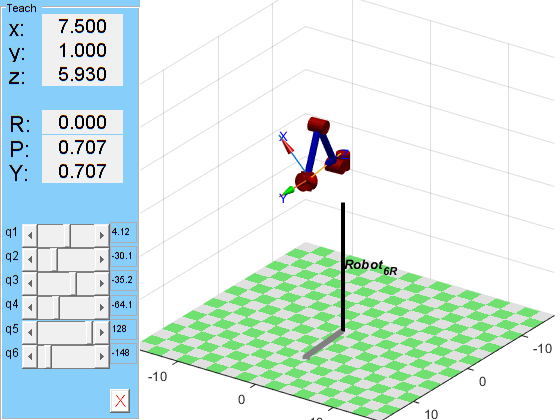

Robot.teach([q1 q2 q3 q4 q5 q6])        % Graficar el robot con el vector q

rad2deg(tr2rpy(Robot.fkine([q1 q2 q3 q4 q5 q6])))   % Ángulos RPY

ans =   -45.0000    0.0000  -90.0000


2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.

Debido a la forma del robot también se puede obtener una configuración de codo abajo como la que se muestra en la figura.

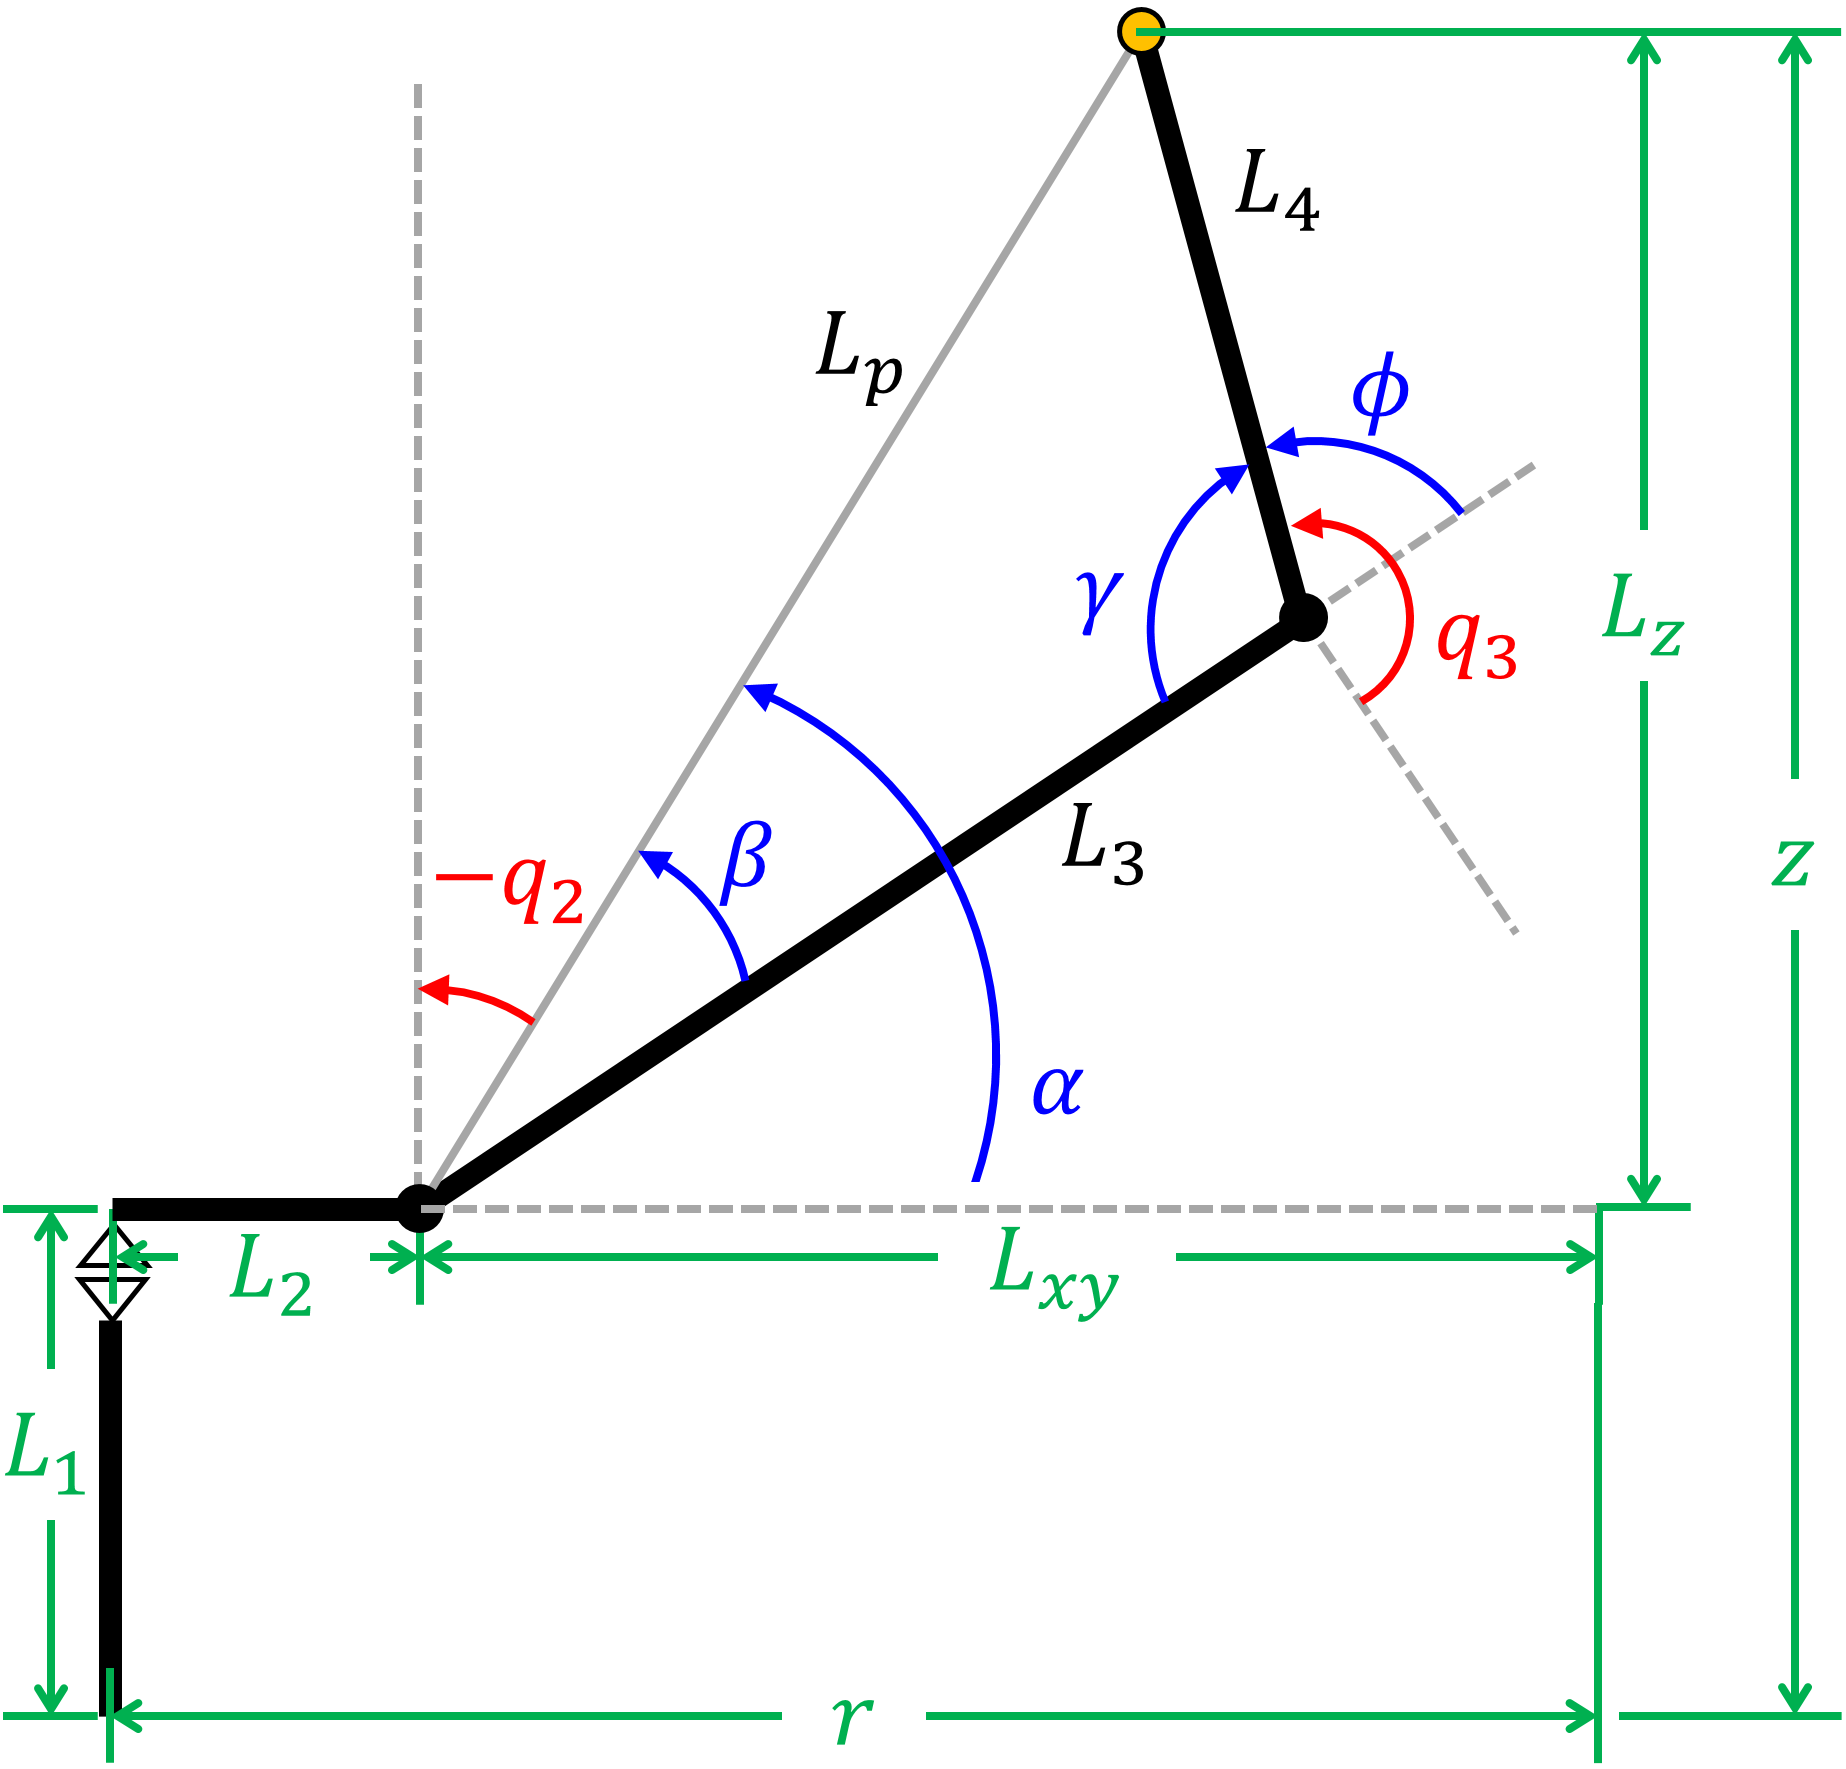

En este caso cambia la forma en la que están definidos $q_2$ y $q_3$ quedando:


$$q_2 = -\left(\frac{\pi}{2} - (\alpha - \beta)\right)$$



$$q_3 = \frac{\pi}{2} + \phi$$


% Valor q2 
q2 = -((pi/2) - (alpha - beta));
% Valor q3 
q3 = (pi/2) + phi;

Volviendo a calcular $q_4$, $q_5$ y $q_6$ entonces:

MTH03 = L(1).A(q1)*L(2).A(q2)*L(3).A(q3); % MTH de 3 con respecto a la base
[R03, P03] = tr2rt(MTH03);              % Separar rotación y translación
[RT6, PT6] = tr2rt(Robot.tool^(-1));    % Matriz de rotación de 6 con respecto al TCP

R06 = R0T*RT6;                          % Matriz de rotación de 6 con respecto a la base
R36 = (R03^(-1))*R06;                   % Matriz de rotación de 6 respecto a 3
% Valor q4 
q4 = atan2(R36(3,3),R36(1,3));
% Valor q5 
c5 = -R36(2,3);
s5 = sqrt(1 - c5^2);
q5 = atan2(s5,c5);
% Valor q6 
q6 = atan2(-R36(2,2),R36(2,1));

% Vector de posiciones artiulares en grados
[rad2deg(q1) rad2deg(q2) rad2deg(q3) rad2deg(q4) rad2deg(q5) rad2deg(q6)]

ans =     4.1211 -138.4104  215.1829  -80.9504   45.5751  -18.6370


En este caso también se logra apreciar que los valores de posición y orientación son correctos.

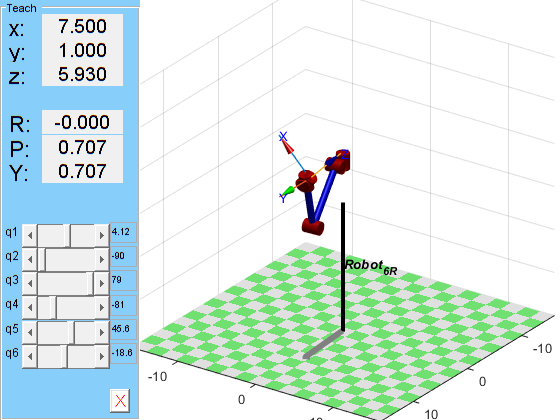

clf
Robot.teach([q1 q2 q3 q4 q5 q6])        % Graficar el robot con el vector q

rad2deg(tr2rpy(Robot.fkine([q1 q2 q3 q4 q5 q6])))   % Ángulos RPY

ans =   -45.0000   -0.0000  -90.0000


Además de las ya presentadas anteriormente, se encuentran otras dos configuraciones las cuales corresponden a cuando  la base el robot gira 180º y el brazo se dobla hacia atrás en configuraciones codo arriba y codo abajo. A continuación se representa la de codo arriba con base rotada.

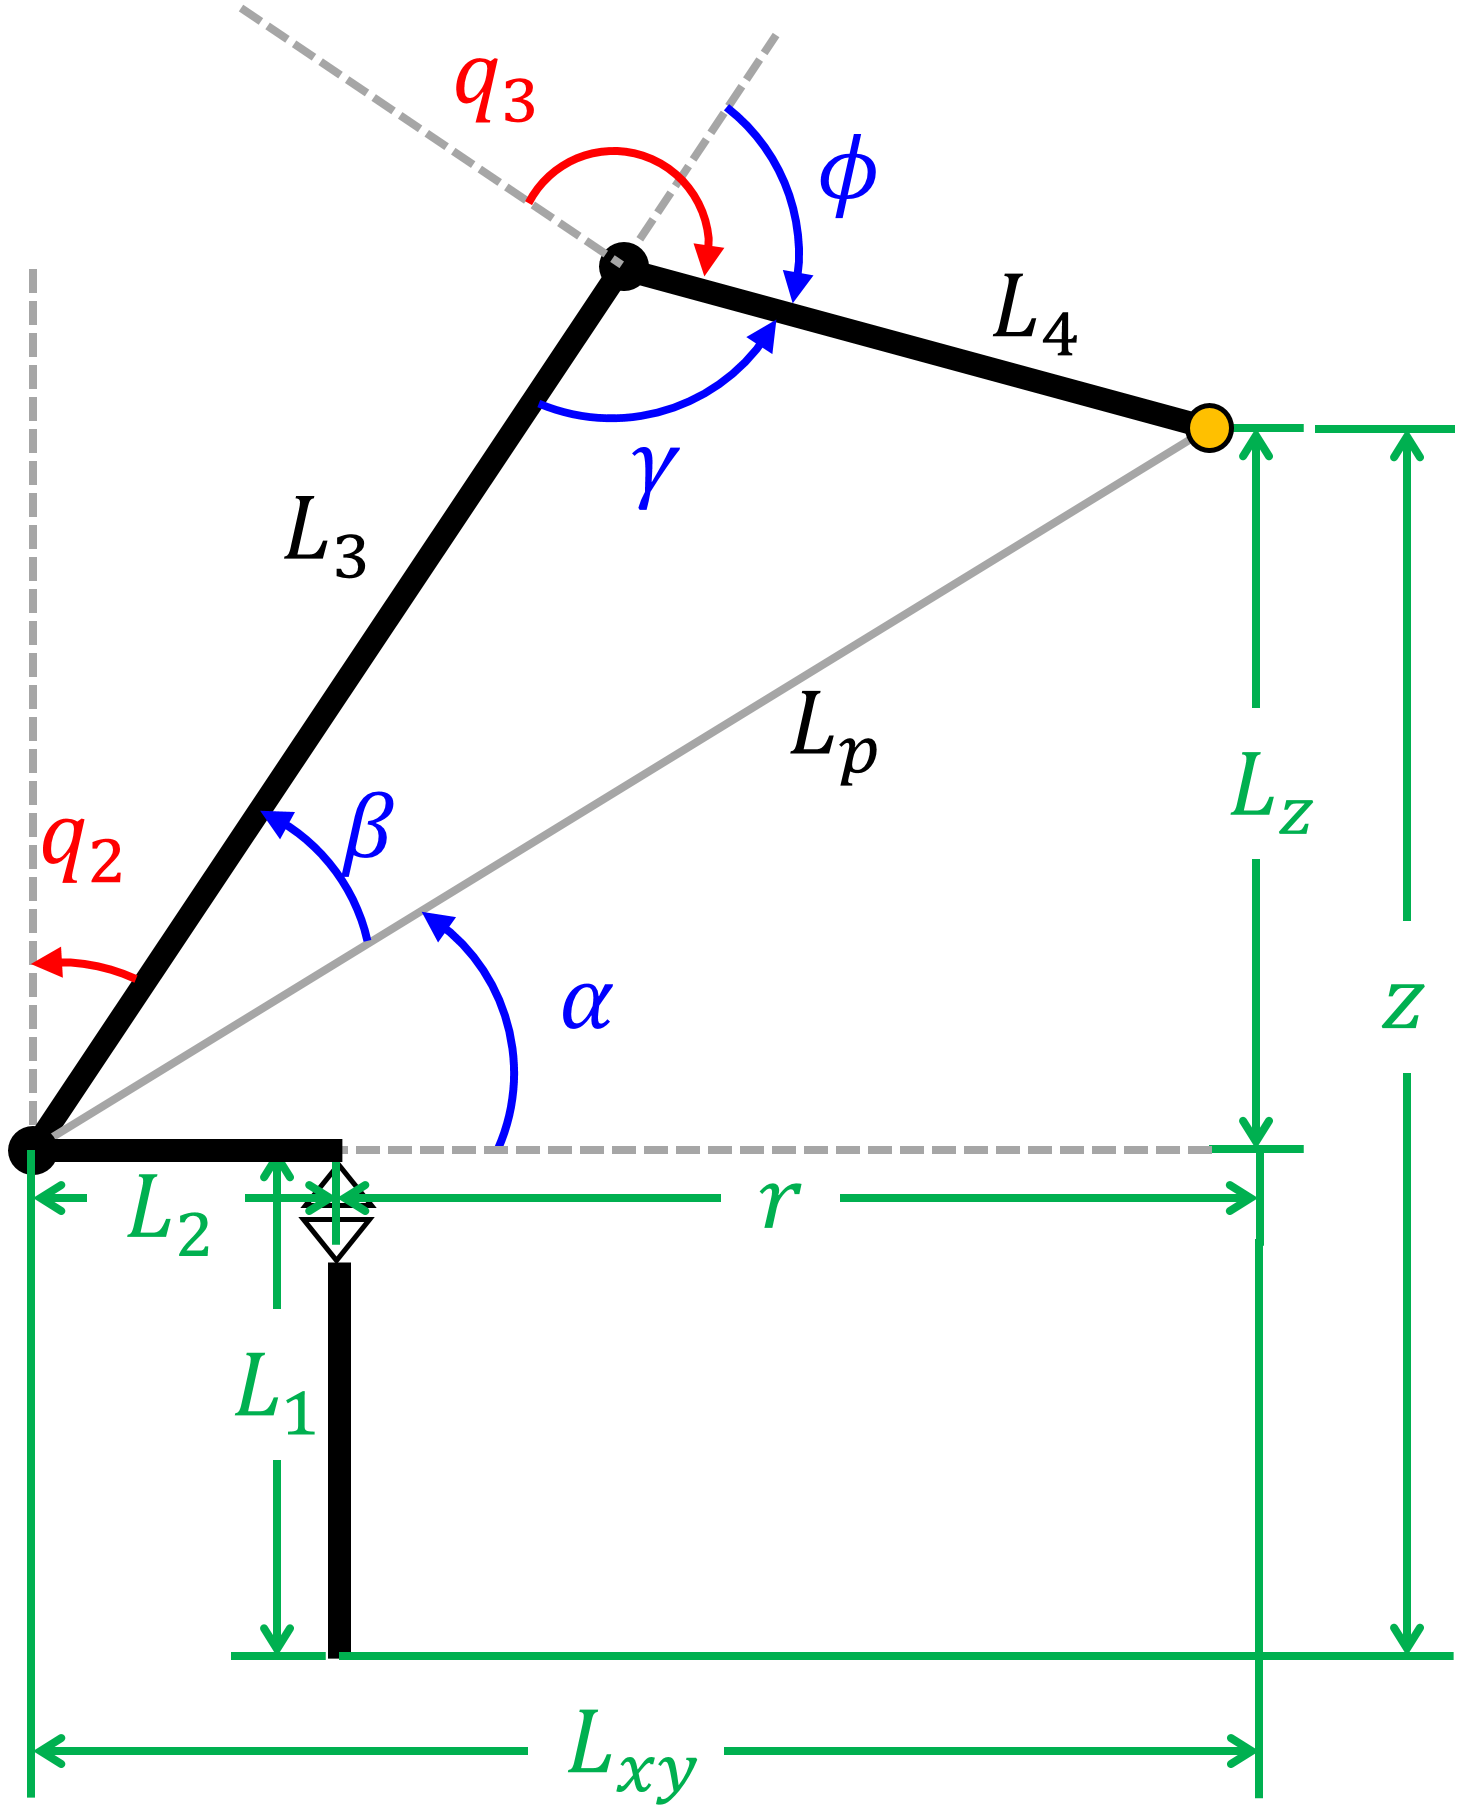

Para esta configuración cambia:


$$L_{xy} = r + L_2$$



$$q_1 = atan2(-y_w,-x_w)$$



$$q_2 = \frac{\pi}{2} - (\alpha + \beta)$$



$$q_3 = \frac{\pi}{2} + \phi$$


Por lo tanto:

Lxy = r + L2;
Lp = sqrt(Lxy^2 + Lz^2);

q1 = atan2(-yw,-xw);                    % Valor q1

alpha = atan2(Lz, Lxy);
cosB = (L3^2 + Lp^2 - L4^2)/(2*L3*Lp);
senB = sqrt(1 - cosB^2);
beta = atan2(senB, cosB);
q2 = ((pi/2) - (alpha + beta));         % Valor q2 

cosY = (L3^2 + L4^2 - Lp^2)/(2*L3*L4);
senY = sqrt(1 - cosY^2);
gama = atan2(senY, cosY);
phi = pi - gama;
q3 = (pi/2) + phi;                      % Valor q3

MTH03 = L(1).A(q1)*L(2).A(q2)*L(3).A(q3); % MTH de 3 con respecto a la base
[R03, P03] = tr2rt(MTH03);              % Separar rotación y translación
[RT6, PT6] = tr2rt(Robot.tool^(-1));    % Matriz de rotación de 6 con respecto al TCP

R06 = R0T*RT6;                          % Matriz de rotación de 6 con respecto a la base
R36 = (R03^(-1))*R06;                   % Matriz de rotación de 6 respecto a 3
% Valor q4 
q4 = atan2(R36(3,3),R36(1,3));
% Valor q5 
c5 = -R36(2,3);
s5 = sqrt(1 - c5^2);
q5 = atan2(s5,c5);
% Valor q6 
q6 = atan2(-R36(2,2),R36(2,1));

% Vector de posiciones artiulares en grados
[rad2deg(q1) rad2deg(q2) rad2deg(q3) rad2deg(q4) rad2deg(q5) rad2deg(q6)]

ans =  -175.8789   44.6135  182.2400  126.4350  118.7611 -128.9141


Volviendo a comprobar los valores obtenidos se tiene:

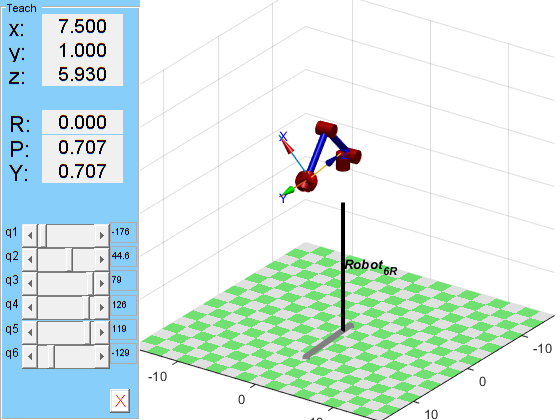

clf
Robot.teach([q1 q2 q3 q4 q5 q6])        % Graficar el robot con el vector q

rad2deg(tr2rpy(Robot.fkine([q1 q2 q3 q4 q5 q6])))   % Ángulos RPY

ans =   -45.0000    0.0000  -90.0000


Por último, se tiene la configuración con codo abajo y base rotada que se muestra en la siguiente figura.

    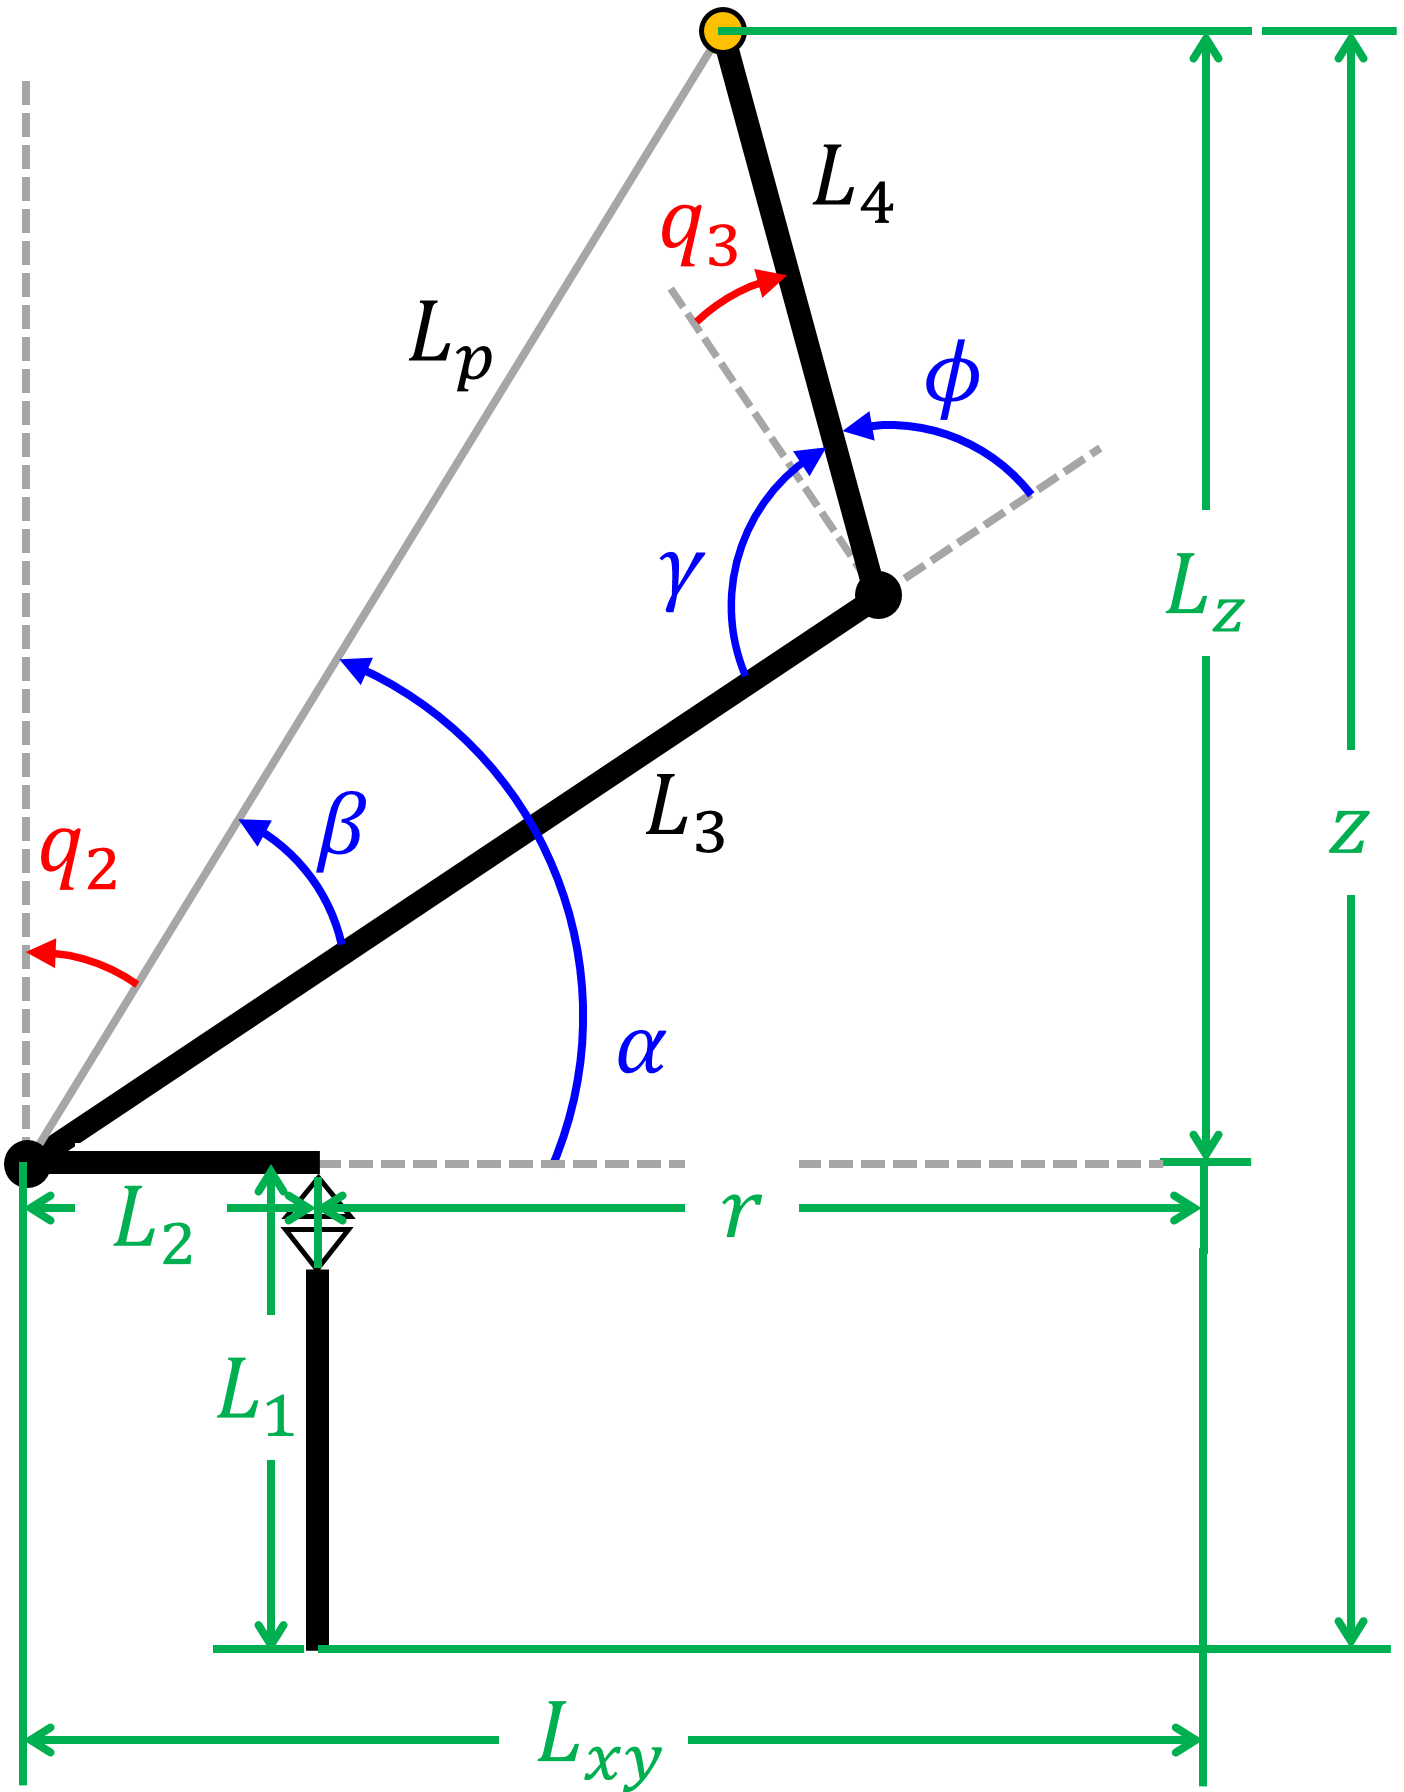

Las modificaciones con respecto a la otra configuración de codo abajo son:


$$L_{xy} = r + L_2$$



$$q_1 = atan2(-y_w,-x_w)$$



$$q_2 = \frac{\pi}{2}  - (\alpha - \beta)$$



$$q_3 = \frac{\pi}{2} - \phi$$


Por consiguiente:

Lxy = r + L2;
Lp = sqrt(Lxy^2 + Lz^2);

q1 = atan2(-yw,-xw);                    % Valor q1

alpha = atan2(Lz, Lxy);
cosB = (L3^2 + Lp^2 - L4^2)/(2*L3*Lp);
senB = sqrt(1 - cosB^2);
beta = atan2(senB, cosB);
q2 = ((pi/2) - (alpha - beta));         % Valor q2

cosY = (L3^2 + L4^2 - Lp^2)/(2*L3*L4);
senY = sqrt(1 - cosY^2);
gama = atan2(senY, cosY);
phi = pi - gama;
q3 = (pi/2) - phi;                      % Valor q3

MTH03 = L(1).A(q1)*L(2).A(q2)*L(3).A(q3); % MTH de 3 con respecto a la base
[R03, P03] = tr2rt(MTH03);              % Separar rotación y translación
[RT6, PT6] = tr2rt(Robot.tool^(-1));    % Matriz de rotación de 6 con respecto al TCP

R06 = R0T*RT6;                          % Matriz de rotación de 6 con respecto a la base
R36 = (R03^(-1))*R06;                   % Matriz de rotación de 6 respecto a 3
% Valor q4 
q4 = atan2(R36(3,3),R36(1,3));
% Valor q5 
c5 = -R36(2,3);
s5 = sqrt(1 - c5^2);
q5 = atan2(s5,c5);
% Valor q6 
q6 = atan2(-R36(2,2),R36(2,1));

% Vector de posiciones artiulares en grados
[rad2deg(q1) rad2deg(q2) rad2deg(q3) rad2deg(q4) rad2deg(q5) rad2deg(q6)]

ans =  -175.8789  127.7067   -2.2400  117.6119   52.7431  -46.6448


Comprobando nuevamente, se aprecia que la posición y la orientación son las dadas inicialmente:

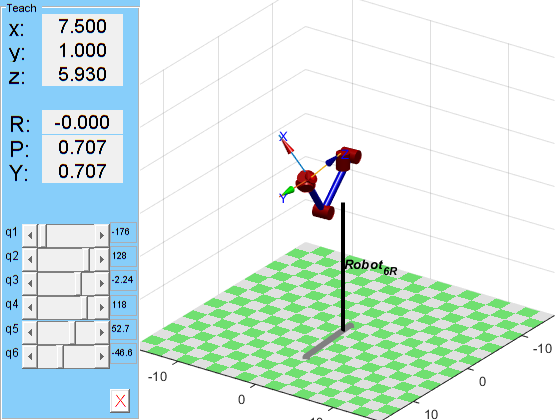

clf
Robot.teach([q1 q2 q3 q4 q5 q6])        % Graficar el robot con el vector q

rad2deg(tr2rpy(Robot.fkine([q1 q2 q3 q4 q5 q6])))   % Ángulos RPY

ans =   -45.0000   -0.0000  -90.0000


3. Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique:

¿Cuál es la diferencia entre estas funciones?

El toolbox de Peter Corke cuenta con 7 funciones para realizar la cinemática inversa de un robot, las cuales se diferencian unas de otras debido al número de articulaciones del robot, la configuración de la muñeca, el método de cálculo utilizado o el forma de representación de los parámetros de Denavit-Hartenberg (DH). Dichas funciones disponibles son:

- **ikine: **Permite calcular la cinemática inversa de un robot de 6 grados de libertad (GDL) o más. Recibe como entrada la matriz de transformación homogénea del efector final ($T$) y como opcional un vector de coordenadas articulares iniciales estimadas ($q_0$), un vector máscara ($m$) para poder usar la función con manipuladores de menos de 6 GDL y algunas opciones para el método de cálculo.

- **ikine6s:** A diferencia de $ikine$, se usa para cálculo de la cinemática inversa en robots de 6 GDL que presentan muñeca esférica y sólo se puede aplicar a manipuladores creados con la representación de DH estándar. Tiene como entrada a $T$ y como parámetro opcional las diferentes configuraciones en las que se puede calcular el robot, como brazo a la derecha o izquierda ($'r'$ o $'l'$), codo arriba o codo abajo ($'u'$ o $'d'$) y muñeca rotada o no rotada 180º ($'f'$ o $'n'$).

- **ikine3:** Esta función se emplea para robots sin muñeca, es decir, de 3 GDL, en las cuales sus articulaciones estén dispuestas como las tres primeras articulaciones de un robot Puma 560. Al igual que $ikine6s$, esta función sólo es aplicable para robots creados con DH estándar y además sus entradas son similares. Debido a que no posee muñeca, las opciones de muñeca rotada o no rotada 180º ($'f'$ o $'n'$) no se encuentran disponibles.

- **ikunc: **Se utiliza para el cálculo (por medio de optimización) de robots con cualquier número de grados de libertad y creados con representaciones DH estándar o DH modificado. Tiene como entradas a $T$, $q_0$ (en caso de tener un vector de coordenadas articulares iniciales estimadas) y algunas opciones provenientes de $fminunc$. Aparte de la cinemática inversa, también permite ver el error y el estado de $fminunc$. Esta función no tiene en cuenta los límites articulares.

- **ikcon:** Al igual que el anterior, permite el cálculo para cualquier robot (sin importar el número de GDL) usando optimización. Sus entradas y salidas son similares, pero algunas de las opciones son de $fmincon$. La principal diferencia radica en que esta función si tiene en cuenta los límites articulares del robot.

- **ikine_sym:** Permite calcular la cinemática inversa simbólica de un robot creado a partir de DH estándar. Sus entradas son el número de soluciones y la opción de escribir la solución en una archivo m-file. 

- **ikinem:** Con esta función es posible hallar la cinemática inversa por medio de minimización. Recibe como entradas a $T$ y de manera opcional a $q_0$ y algunas opciones de configuración del método de cálculo.  

¿Cuál debe usar para su robot y por qué? (Revise la documentación del Toolbox)

 Para el robot con el cual se está trabajando actualmente (ABB IRB 1600) se puede hacer uso de las funciones $ikine$ e $ikunc$ debido a que permiten hallar la cinemática inversa en robots de 6 GDL. No se hace uso de $ikin6s$ debido a que al calcular los parámetros de DH estándar para dicho robot, el eje de coordenadas 4 queda en el mismo origen del marco de coordenadas 3 y no junto a los marcos de coordenadas 5 y 6, razón por la cual $Matlab$ la toma como si no fuera un muñeca esférica y no la deja calcular.

A continuación se muestra la implementación de $ikine$:

% Uso de ikine
% Valores de prueba
xe = 750/100;
ye = 100/100;
ze = 593/100;
roll = -45;
pitch = 0;
yaw = -90;

R0T = rpy2r(roll, pitch, yaw, 'deg');
pe = [xe; ye; ze];

T = rt2tr(R0T, pe)

T =     0.0000    1.0000         0    7.5000
   -0.7071    0.0000    0.7071    1.0000
    0.7071   -0.0000    0.7071    5.9300
         0         0         0    1.0000


q_ikine = Robot.ikine(T)

q_ikine =     0.0144   -0.4316   -0.4968    0.3908   -1.3441    1.8801


Al utilizar la función $ikine$ se puede observar que la solución no logra llegar a la posición y orientación deseada y, además, presenta un error de 144,083 después de la iteración 1000. Por consiguiente, se procede a implementar $ikunc$.

% Uso de ikunc
q_ikunc = Robot.ikunc(T)

q_ikunc =     0.0719   -0.5254   -0.6141   -1.1195    2.2409   -2.5806


deg_ikunc = rad2deg(q_ikunc)

deg_ikunc =     4.1211  -30.1036  -35.1829  -64.1444  128.3963 -147.8546


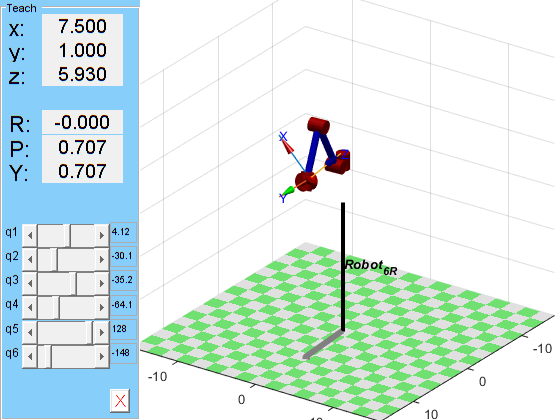

clf
Robot.teach(q_ikunc);

rad2deg(tr2rpy(Robot.fkine(q_ikunc)))

ans =   -45.0000   -0.0000  -90.0000


Como se logra ver, el vector de posición articular generalizado encontrado por esta función permite ubicar el robot en los parámetros deseados, por lo tanto, se utiliza para calcular la cinemática inversa por iteración.

Al comparar el resultado con los métodos analíticos hallados anteriormente se aprecia que la función $ikunc$ encuentra los valores de $q$ para una configuración de robot con codo arriba y sin base rotada.

4. Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.

 Para calcular la cinemática inversa empleando el toolbox de RST primero se importa el robot usando $loadrobot$ y especificando que es el ABB IRB 1600. Luego se usa $inverseKinematics$ para definir la cinemática inversa de dicho manipulador, en esta se introducen como parámetros el robot y se especifica que es $'RigidBodyTree'$. Se define un vector con unos para especificar que todo debe tener la misma precisión, se brinda una posición inicial de los valores de $q$, la posición del efector final y luego se calculan los valores de $q$. Esto se muestra a continuación:

% Importar robot
[robotRBT,robotData]= loadrobot('abbirb1600','DataFormat','row','Gravity',[0 0 -9.81]);

% Valores de prueba
xe = 750/1000;
ye = 100/1000;
ze = 593/1000;
roll = -45;
pitch = 0;
yaw = -90;

R0T = rpy2r(roll, pitch, yaw, 'deg');   % Matriz de orientación del efector final
pe = [xe; ye; ze];                      % Vector de posición del efector final

T = rt2tr(R0T, pe);                     % MTH en el efector final

ik = inverseKinematics('RigidBodyTree',robotRBT);   % Cinemática inversa    
weights = [1 1 1 1 1 1];                            % Vector para que todo tenga la misma precisión
initialguess = robotRBT.homeConfiguration;          % Configuración inicial
[configSoln,solnInfo] = ik('tool0',T,weights,initialguess); % MTH efector final
configSoln

configSoln =     0.0719    0.3146    0.3955   -0.8917   -2.0069   -2.1545


rad2deg(configSoln)

ans =     4.1211   18.0240   22.6626  -51.0887 -114.9890 -123.4425



q = [configSoln(1) -configSoln(2) -configSoln(3) configSoln(4) -configSoln(5) configSoln(6)]

q =     0.0719   -0.3146   -0.3955   -0.8917    2.0069   -2.1545


rad2deg(tr2rpy(Robot.fkine(q)))

ans =   -45.0000    0.0000  -90.0000


5. Compare los métodos.

 Como se logró apreciar, los tres métodos utilizados permiten encontrar de manera correcta los valores del vector de posición articular generalizado $q$. En el caso del primer método, se lograron encontrar 4 configuraciones del robot diferentes para llegar al mismo punto. Esto se logró haciendo el desarrollo por el método geométrico (para las tres primeras articulaciones) y por análisis de las matrices de rotación (para las últimas tres articulaciones).

En el caso de la función $ikunc$, dicho cálculo lo realiza por medio de iteración usando optimización y la configuración con la cual calcula los valores de $q$ es la de codo arriba sin rotar la base.

Finalmente, la función $inverseKinematics$ calcula cinemática inversa de un robot creado o importado con el *Robotics System Toolbox *y presenta una configuración del robot diferente a las mostradas anteriormente.

6. Calcule la configuración del robot para las siguientes posturas de la herramienta. Proponga 4 posturas (x, y, z, roll, pitch, yaw)’ que estén dentro del espacio de trabajo y determine la configuración del manipulador y complete la tabla 2.

A continuación se ingresan 4 posturas con el fin de calcular los valores de $q$. También se va comprobando que los valores de pisción y orientación sean correctos.

% Primera postura
xe = 59.243/100;
ye = -335.984/100;
ze = 1401.93/100;
roll = 69.332;
pitch = 35.079;
yaw = -24.999;

% Cinemática inversa
[q1, q2, q3, q4, q5, q6] = CinIversa(xe, ye, ze, roll, pitch, yaw, L1, L2, L3, L4, L5, L,...
                                     Robot, "codoArriba");

ans =    -1.4945    0.5706   -0.0324   -1.8825    0.5713    3.0397


ans =   -85.6270   32.6955   -1.8574 -107.8588   32.7315  174.1599


[~, pos] = tr2rt(Robot.fkine([q1 q2 q3 q4 q5 q6]))  % Posición efector final

pos =     0.5924
   -3.3598
   14.0193


rad2deg(tr2rpy(Robot.fkine([q1 q2 q3 q4 q5 q6])))   % Orientación efector final

ans =    69.3320   35.0790  -24.9990


% Segunda postura
xe = -184.811/100;
ye = -184.811/100;
ze = 1324.00/100;
roll = 0.000;
pitch = 0.000;
yaw = 135.000;

% Cinemática inversa
[q1, q2, q3, q4, q5, q6] = CinIversa(xe, ye, ze, roll, pitch, yaw, L1, L2, L3, L4, L5, L,...
                                     Robot, "codoArriba");

ans =    -2.3562    0.6847   -0.2908    0.0000    1.1769   -1.5708


ans =  -135.0000   39.2290  -16.6615    0.0000   67.4325  -90.0000


[~, pos] = tr2rt(Robot.fkine([q1 q2 q3 q4 q5 q6]))  % Posición efector final

pos =    -1.8481
   -1.8481
   13.2400


rad2deg(tr2rpy(Robot.fkine([q1 q2 q3 q4 q5 q6])))   % Orientación efector final

ans =     0.0000   -0.0000  135.0000


% Tercera postura
xe = -4.561/100;
ye = -261.322/100;
ze = 1324.000/100;
roll = 128.751;
pitch = 36.984;
yaw = -25.773;

% Cinemática inversa
[q1, q2, q3, q4, q5, q6] = CinIversa(xe, ye, ze, roll, pitch, yaw, L1, L2, L3, L4, L5, L,...
                                     Robot, "codoArriba");

ans =    -1.7660    0.6662   -0.1043   -2.3387    1.4182   -2.3503


ans =  -101.1848   38.1732   -5.9764 -133.9981   81.2577 -134.6608


[~, pos] = tr2rt(Robot.fkine([q1 q2 q3 q4 q5 q6]))  % Posición efector final

pos =    -0.0456
   -2.6132
   13.2400


rad2deg(tr2rpy(Robot.fkine([q1 q2 q3 q4 q5 q6])))   % Orientación efector final

ans =   128.7510   36.9840  -25.7730


% Cuarta postura
xe = 709.004/100;
ye = 128.937/100;
ze = 412.364/100;
roll = -172.783;
pitch = 19.295;
yaw = -152.429;

% Cinemática inversa
[q1, q2, q3, q4, q5, q6] = CinIversa(xe, ye, ze, roll, pitch, yaw, L1, L2, L3, L4, L5, L,...
                                     Robot, "codoArriba");

ans =     0.1745   -0.6198   -0.7129   -0.4754    0.1301    1.1597


ans =    10.0000  -35.5118  -40.8452  -27.2367    7.4562   66.4477


[~, pos] = tr2rt(Robot.fkine([q1 q2 q3 q4 q5 q6]))  % Posición efector final

pos =     7.0900
    1.2894
    4.1236


rad2deg(tr2rpy(Robot.fkine([q1 q2 q3 q4 q5 q6])))   % Orientación efector final

ans =  -172.7830   19.2950 -152.4290


En resumen se obtuvo que:

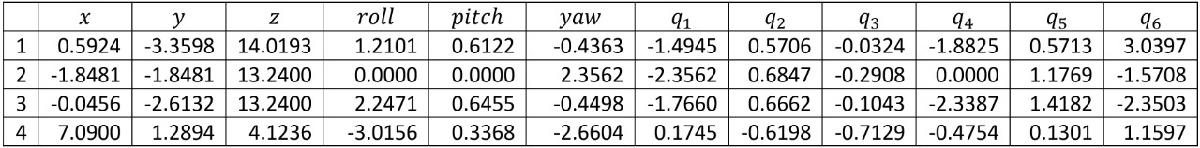

7. y 8. Haciendo uso de la GUI verifique que con la configuración calculada se obtiene la postura indicada de la herramienta. Para uno de los cuatro casos haga capturas de pantalla resaltando con cotas los valores x y z, e incluya en el informe los resultados.

A continuación se presentan las 4 posturas calculadas anteriormente y mostradas en la GUI. En ellas se muestra el robot, el valor de cada $q$, y las coordenadas de posición y orientación.

**Primera postura**

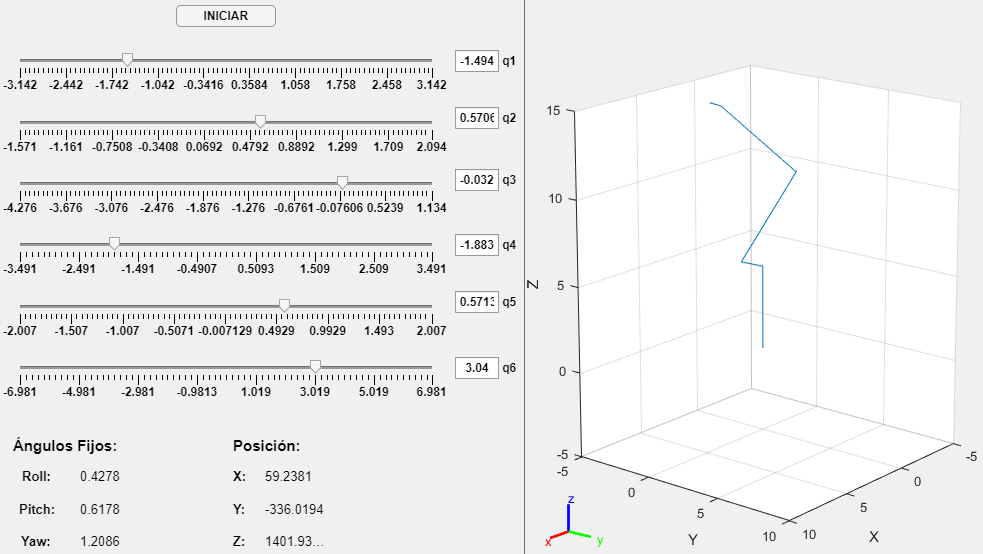

**Segunda postura**

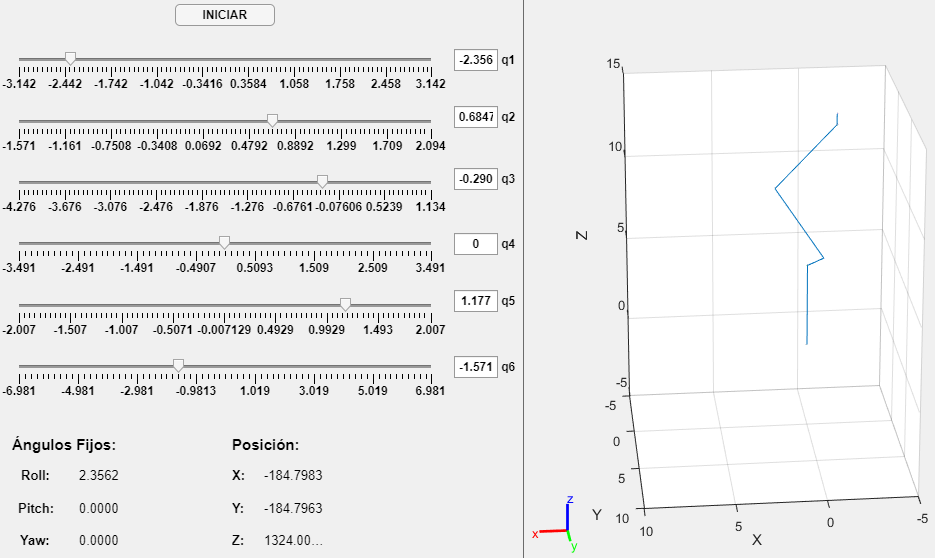

**Tercera postura**

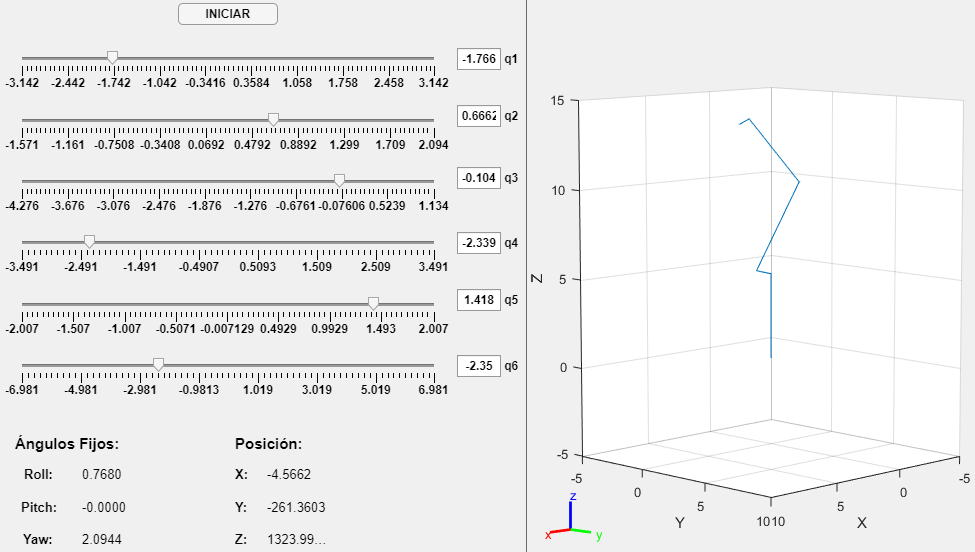

**Cuarta postura**